# สัญญาณและระบบแบบเวลาไม่ต่อเนื่อง (Discrete-time Signal & System)

# ตอนที่ 2 : สัญญาณและระบบแบบเวลาไม่ต่อเนื่อง (Discrete-time Signal & System)

เมื่อเราทำการวิเคราะห์หรือสังเคราะห์สัญญาณและระบบแบบเวลาไม่ต่อเนื่อง เ**ราจะกำหนดให้ตัวแปรอิสระ (indepedent variable) เป็นจำนวนเต็ม **$n$ ที่บ่งบอกถึงรอบในการคำนวณ (iteration) 

เราสามารถอธิบายร**ะบบพลวัตแบบเวลาไม่ต่อเนื่องในรูปของสมการผลต่าง (difference equation)** ที่จัดเป็นสมการปริภูมิสถานะ (state-space) โดยมีรูปแบบดังต่อไปนี้


$$\begin{array}{l}
\mathbf{x}\left\lbrack n+1\right\rbrack =\mathbf{f}\left(\mathbf{x}\left\lbrack n\right\rbrack ,\mathbf{u}\left\lbrack n\right\rbrack \right)\\
\mathit{\mathbf{y}}\left\lbrack n\right\rbrack =\mathbf{g}\left(\mathbf{x}\left\lbrack n\right\rbrack ,\mathbf{u}\left\lbrack n\right\rbrack \right)
\end{array}$$


หากระบบเป็น LTI เราสามารถเขียนสมการแสดงปริภูมิสถานะได้ดังต่อไปนี้


$$\begin{array}{l}
\mathbf{x}\left\lbrack n+1\right\rbrack =\mathbf{A}\cdot \mathbf{x}\left\lbrack n\right\rbrack +\mathbf{B}\cdot \mathbf{u}\left\lbrack n\right\rbrack \\
\mathit{\mathbf{y}}\left\lbrack n\right\rbrack =\mathbf{C}\cdot \mathbf{x}\left\lbrack n\right\rbrack +\mathbf{D}\cdot \mathbf{u}\left\lbrack n\right\rbrack 
\end{array}$$


ในเชิงของการนำสมการไปเขียนในโปรแกรม เราจะไม่สามารถเขียนสมการเชิงอนุพันธ์ได้เนื่องจากการทำงานของคอมพิวเตอร์หรือไมโครคอนโทรลเลอร์ทำงานเป็นทีละขั้นตอน ดังนั้น**การคำนวณแบบเวลาต่อเนื่อง (อนุพันธ์) จึงไม่สามารถเขียนตรงๆได้** เราทำได้ดีสุดคือการประมาณโดยใช้ระเบียบเชิงตัวเลข (numerical method) 

ในทางกลับกัน **เราสามารถเขียนสมการเชิงผลต่างในโปรแกรมได้เนื่องจากการทำงานของคอมพิวเตอร์หรือไมโครคอนโทรลเลอร์เป็นแบเวลาไม่ต่อเนื่อง**

ดังนั้น เราจะสังเคราะห์และเขียนโปรแกรมระบบต่างๆเป็นเวลาไม่ต่อเนื่อง ซึ่งหลายครั้งจะเกิดมาจากการประมาณระบบแบบเวลาต่อเนื่อง

## ตัวอย่างที่ 1 : การเฉลี่ยเคลื่อนที่ (Moving average)

กำหนดให้สัญญาณอินพุต $u\left\lbrack n\right\rbrack$ และสัญญาณเอ้าท์พุต $y\left\lbrack n\right\rbrack$ มีความสัมพันธ์ดังต่อไปนี้


$$\begin{array}{l}
y\left\lbrack n\right\rbrack =\frac{1}{2}\left(x\left\lbrack n\right\rbrack +u\left\lbrack n\right\rbrack \right)\\
x\left\lbrack n+1\right\rbrack =u\left\lbrack n\right\rbrack \\
x\left\lbrack 0\right\rbrack =0
\end{array}$$


โดยที่ $x\left\lbrack n\right\rbrack$ เป็นสถานะของระบบ 

ความสัมพันธ์ที่ถูกกำหนดนับว่าเป็นระบบพลวัตแบบเวลาไม่ต่อเนื่องเพราะว่าความสัมพันธ์นั้นขึ้นอยู่อยู่กับตัวแปรสถานะด้วย

$y\left\lbrack n\right\rbrack$. $u\left\lbrack n\right\rbrack$, และ $x\left\lbrack n\right\rbrack$ นับว่าเป็นสัญญาณ แต่ความสัมพันธ์ทั้งหมดนับว่าเป็นระบบ 

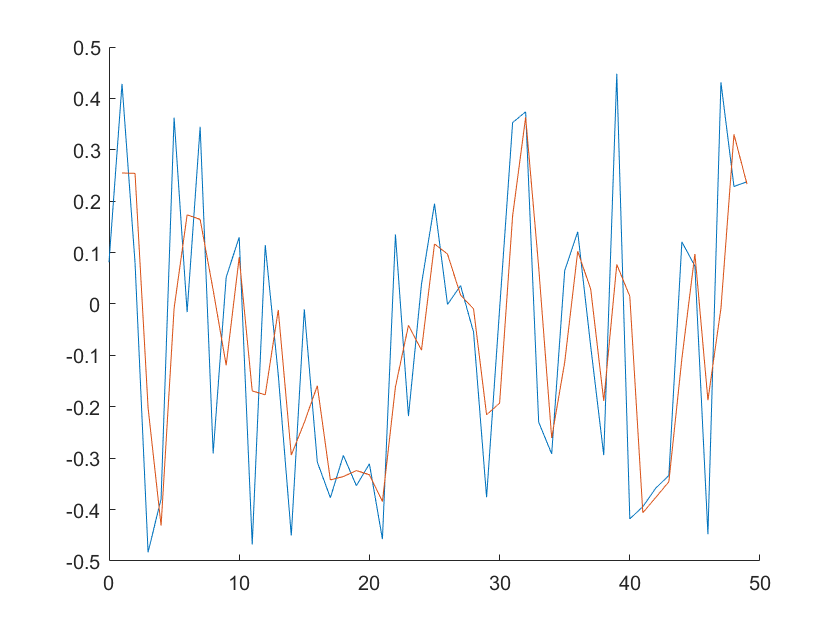

N = 50;
u = rand(N,1)-0.5;
y = 0.5*(u(1:end-1)+u(2:end));
n = linspace(0,N-1,N);
clf;
ax = axes;
hold(ax,'on')
plot(ax,n,u)
plot(ax,n(2:end),y)

เราสามารถนำความสัมพันธ์ดังกล่าวไปเขียนเป็นโปรแกรมของไมโครคอนโทรลเลอร์ได้ดังต่อไปนี้ (pseudo-code)